**Assignment 1**

**Part1**

clc
clear all
%% Boundary Value Problem (BVP)
% Symbolic variables
syms E A rho L g s real % Constants
syms x u(x) r(x) q real %Variables

syms epsilon sigma real % Others

% Constants definitions

rho=pi^3/L^2;
s=g*pi^4/L^2;
F=A*E*g*pi^2/L;
r=(x/L)^2;

% Distributed force
q=E*(rho*u-s*r);

%Hooke's law
epsilon=diff(u,x);
sigma=E*epsilon;

% Equilibrium
eq1 = diff(sigma,x)+q==0;

% Boundary conditions
cond1 = u(0) == -g; % Displacement 
du_dx_L = diff(u,x);
cond2 = A*E*subs(du_dx_L,x,L) == F; %Force

% General solution 
u_sol = dsolve(eq1, cond1, cond2);

$$u\_sol = \begin{array}{l} \frac{27418221630202000\,g\,x^{2}}{8727491006471547\,L^{2}}-\frac{60734012678424311367065255549209\,g\,\cos\left(\sigma_{1}\right)}{76169099268041736439034920573209}-\frac{15435086589617425071969665024000\,g}{76169099268041736439034920573209}+\frac{\sqrt{969721222941283}\,\sin\left(\sigma_{1}\right)\,\left(25630577700916340525091638990194156534388310045\,g-1018947649252663211456509078444278022144\,\sqrt{969721222941283}\,g\,\sin\left(\frac{3\,\sqrt{969721222941283}}{16777216}\right)\right)}{1239212017299659333113193980149375660544971971600842752\,\cos\left(\frac{3\,\sqrt{969721222941283}}{16777216}\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\sqrt{969721222941283}\,x}{16777216\,L} \end{array}$$

u_sol_simp = vpa(u_sol,4)

$$u\_sol\_simp = 1.545\,g\,\sin\left(\frac{5.568\,x}{L}\right)-0.7974\,g\,\cos\left(\frac{5.568\,x}{L}\right)-0.2026\,g+\frac{3.142\,g\,x^{2}}{L^{2}}$$

%% Exact Solution
% Apply numeric values
L_val=1;
g_val=0.01;

% Substitute
aa=(subs(u_sol,[g L], [g_val, L_val]))

$$aa = \frac{274182216302020\,x^{2}}{8727491006471547}-\frac{60734012678424311367065255549209\,\cos\left(\frac{3\,\sqrt{969721222941283}\,x}{16777216}\right)}{7616909926804173643903492057320900}-\frac{\sqrt{969721222941283}\,\sin\left(\frac{3\,\sqrt{969721222941283}\,x}{16777216}\right)\,\left(\frac{254736912313165802864127269611069505536\,\sqrt{969721222941283}\,\sin\left(\frac{3\,\sqrt{969721222941283}}{16777216}\right)}{25}-\frac{5126115540183268105018327798038831306877662009}{20}\right)}{1239212017299659333113193980149375660544971971600842752\,\cos\left(\frac{3\,\sqrt{969721222941283}}{16777216}\right)}-\frac{154350865896174250719696650240}{76169099268041736439034920573209}$$

expr=vpa(aa,4)

$$expr = 0.01545\,\sin\left(5.568\,x\right)-0.007974\,\cos\left(5.568\,x\right)+0.03142\,x^{2}-0.002026$$

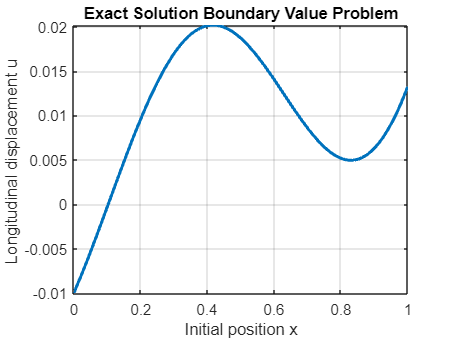


% Plotear la solución
fplot(aa, [0 L_val], 'LineWidth',2)
xlabel('Initial position x')
ylabel('Longitudinal displacement u ')
grid on
title('Exact Solution Boundary Value Problem')